# data cube of specific leaf ID

xCube = multibandread('G:\Shared drives\Leaf_cabinet_data\leaf_2020_cabinet_200919_100050_ID980\leaf_2020_1000ms_80\leaf_2020_1000ms_80_000000\leaf_2020_1000ms_80_000000.dat',[1024,1024,80],'uint16',0,'bsq','ieee-be');

## All the wavelengths used

wv = [500.0,505.1,510.1,515.2,520.3,525.3,530.4,535.4,540.5,545.6,550.6,555.7,560.8,565.8,570.9,575.9,581.0,586.1,591.1,596.2,601.3,606.3,611.4,616.5,621.5,626.6,631.6,636.7,641.8,646.8,651.9,657.0,662.0,667.1,672.2,677.2,682.3,687.3,692.4,697.5,702.5,707.6,712.7,717.7,722.8,727.8,732.9,738.0,743.0,748.1,753.2,758.2,763.3,768.4,773.4,778.5,783.5,788.6,793.7,798.7,803.8,808.9,813.9,819.0,824.1,829.1,834.2,839.2,844.3,849.4,854.4,859.5,864.6,869.6,874.7,879.7,884.8,889.9,894.9,900.0];

## Converting into a hypercube (Camera's .hdr file doesn't conform to contructor function, thus extra work)

hCube = hypercube(xCube,wv);

## applying a crop reduction to hypercube data

row = 102:902;
col = 102:902;
yCube = cropData(hCube,row,col);

## grab all 1024x1024 values in band 50(for testing)

band50 = xCube(:,:,50);

## Create RGB image from cube bands

rgbImg = colorize(hCube);
rgbImgCropped = colorize(yCube);

## perform clustering over entire cube

% Over each raw data band, uncropped
idc = imsegkmeans(cast(xCube,'uint16'),2);
% Over uncropped hypercube rgb
idk = imsegkmeans(cast(rgbImg,'uint16'),2);
% Over cropped rgb
idk1 = imageSegmenter(rgbImgCropped);

Error using imageSegmenter
Too many output arguments.

% Over uncropped hypercube
%test = band80 > 20000;

## Test for circles:

## After segmentation [no crop(RGB), cropped(RGB), no crop(Gray), crop(Gray) ]

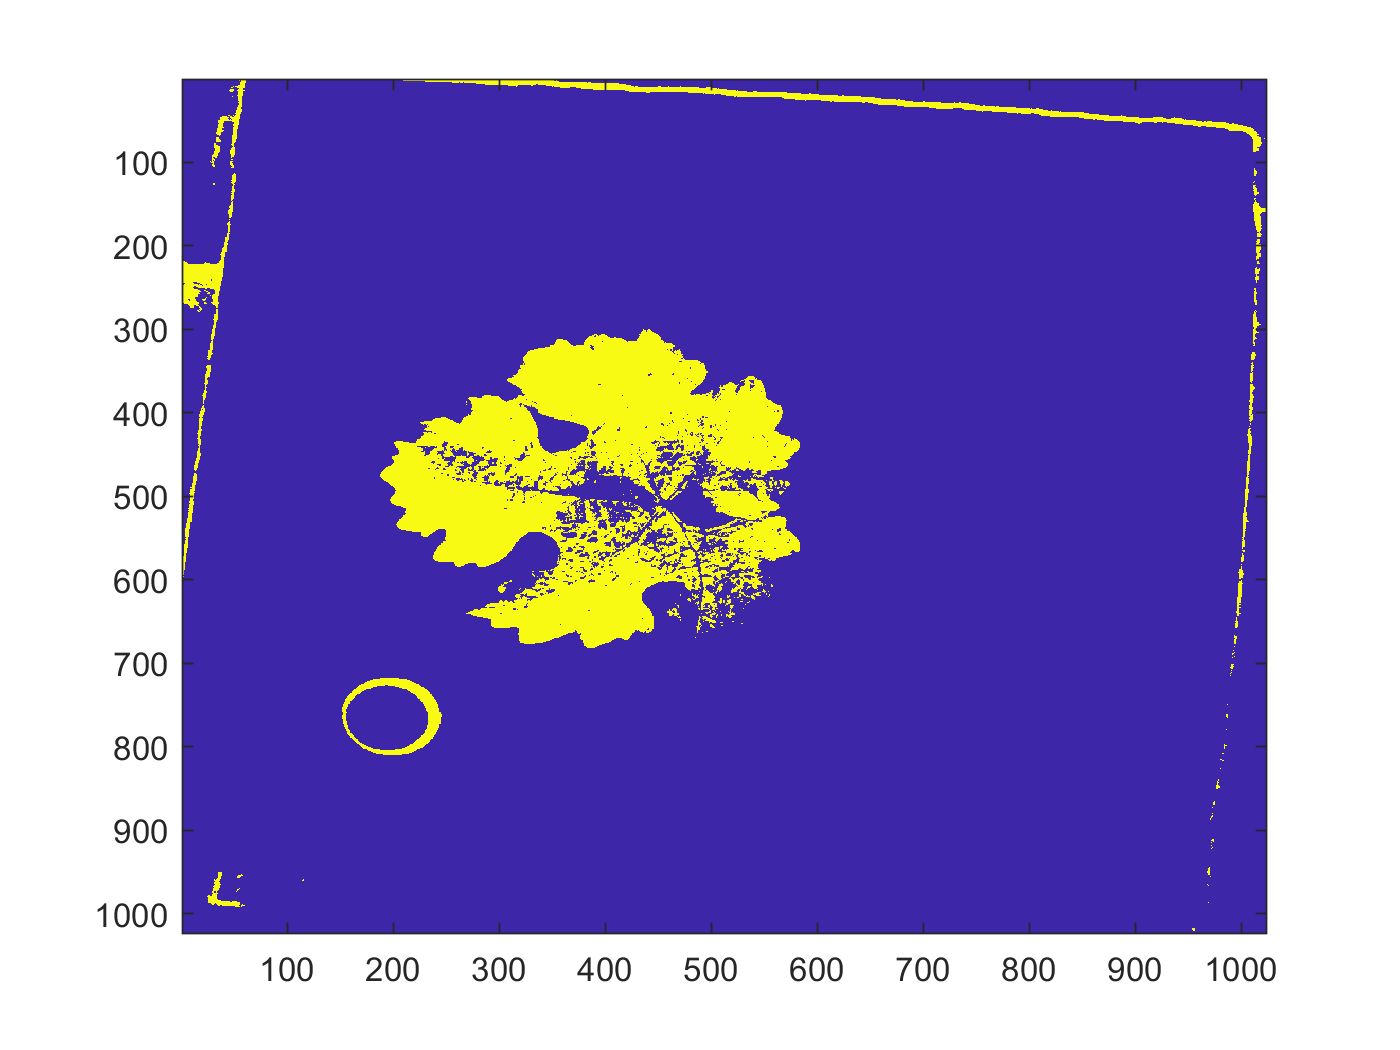

% No crop rgb image
imagesc(idk);

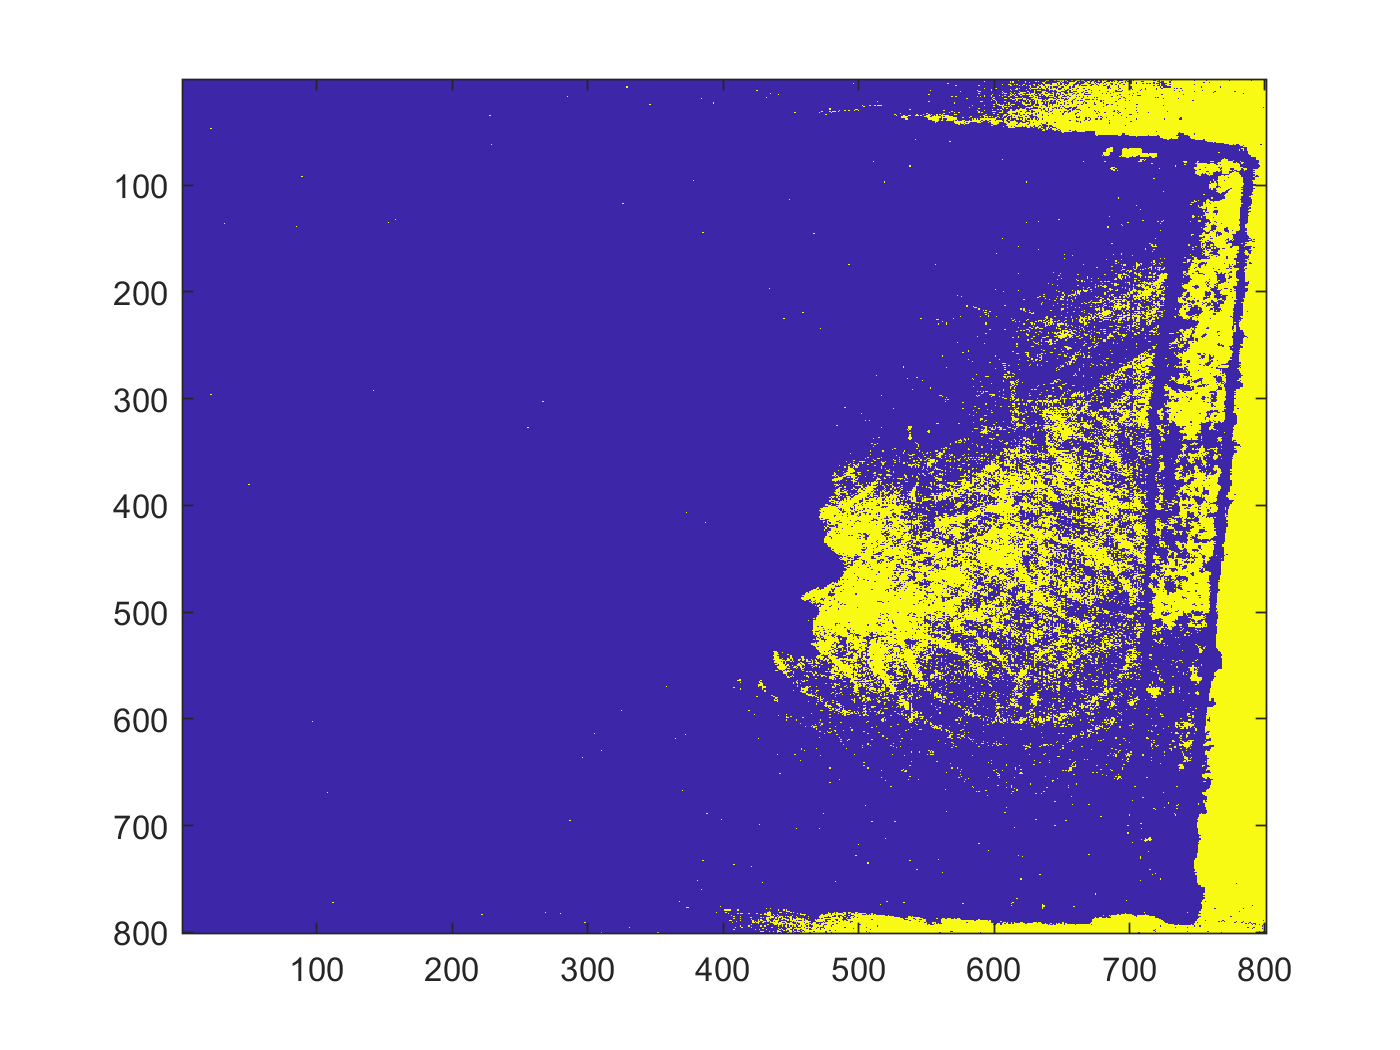

% Cropped rgb image
imagesc(idk1);

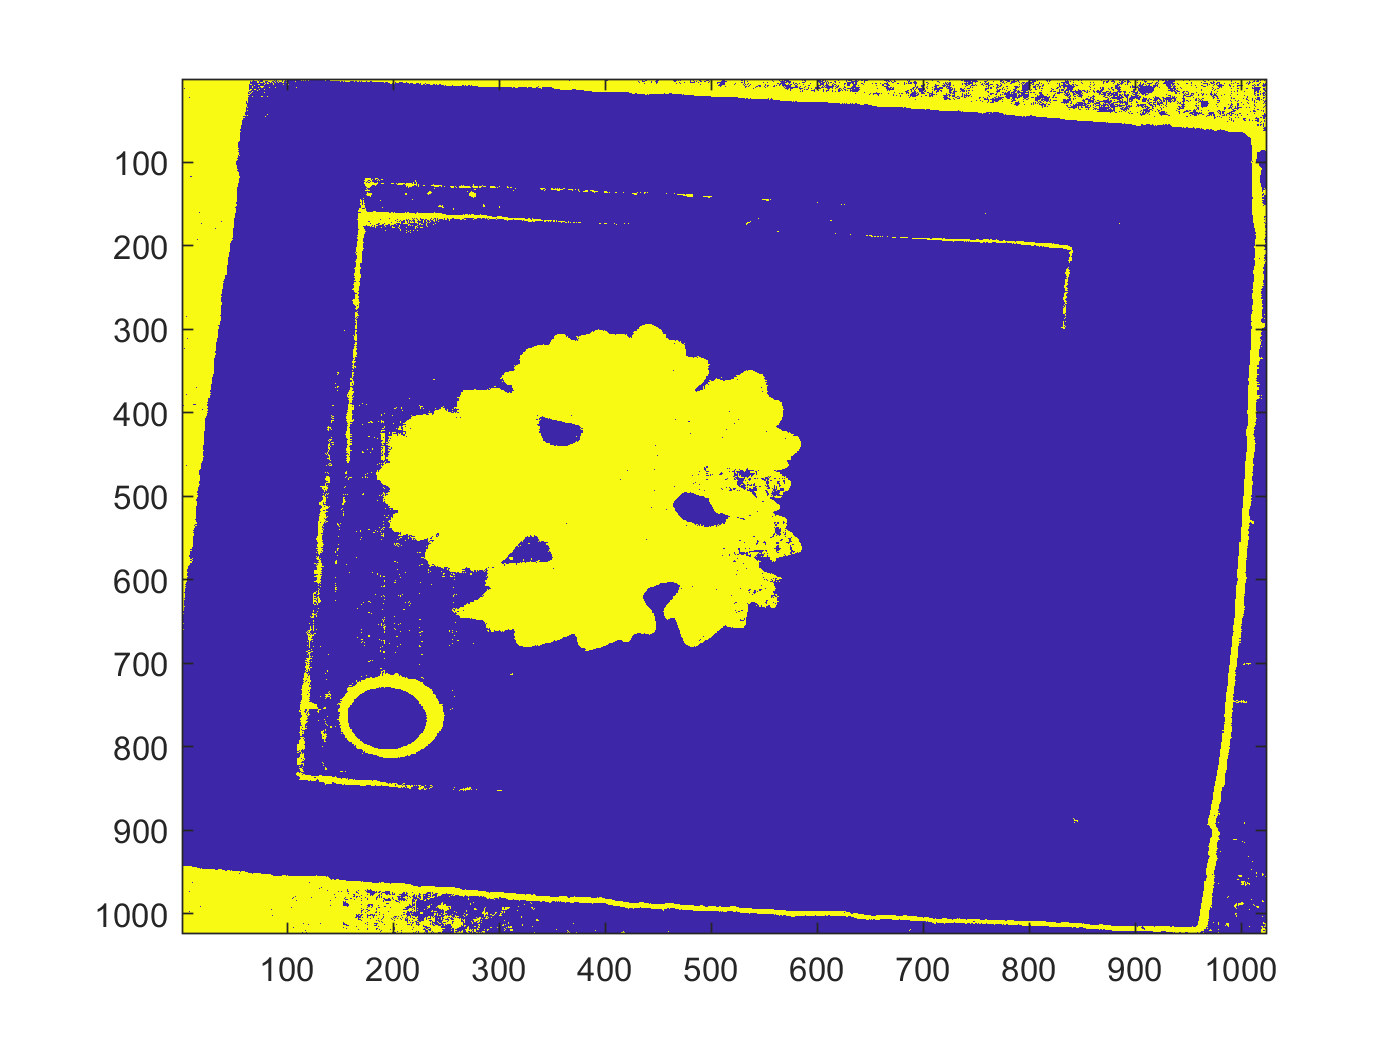

imagesc(idc);

%axis on
%hold on;
%plot(50,100, 'r+');